% Path to the code/scripts
addpath(genpath('/Users/teatompos/Documents/GitHub/PhD_Project1--small-spiking-neural-network'))
addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts/RU_1st_internship_Neurophysiology_Dept/DynaSim'))
clear all; close all

% Saving names prefixes

SaveSim_pre = 'Fig4_Net_';
SaveAn_pre = 'Fig4_Analysis_';
SaveFig_pre = 'Fig4_';

% Path to save figures
FiguresPath = '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Figures/Baseline';
addpath(genpath(FiguresPath))
SaveFigures = 1;

% % Path to save/retrieve results

ResultsPath = '/Volumes/WD_Tea/Work files/PhD at RU/Fig4/Simulations';
addpath(genpath(ResultsPath))

cd(ResultsPath)

Simulate = 0;

if Simulate
    SaveResults = 1;
    
    % limit the number of parallel workers because matlab runs out of memory
    delete(gcp('nocreate'))
    parpool('local', 8);
end

% E-I ratio
Ecells_percentage = 0.85;
Icells_percentage = 0.15;

% Simulation time
tstop = 600;

% baseline connectivity
synStr = 1;
pconn = 1;

% seeds for vpm input
vpm_seeds = [10	28	55	96	97	16	98	36	49	81	15	43	92	80	23	66	4	85	94	68];

% seeds for ctx connectivity
ctx_seeds = [76	75	40	23	18	71	4	28	5	10	83	70	32	96	9	44	39	77	80	19];

% Stimulate baseline conditions
synParams = struct('synstr',[synStr synStr], 'pconn', [pconn pconn]);

if Simulate
    for vpm_input = vpm_seeds
        for ctx_conn = ctx_seeds
            seeds = struct('ctx_seed', ctx_conn,... % fix ctx connectivity
                'vpm_seed', vpm_input);             % fix the vpm activity across repetitions
            
            NetSaveName = sprintf('%s_VPM_seed%i_CTX_seed%i', SaveSim_pre, vpm_input, ctx_conn);
            
            SpikingNetwork = SimN4(Ecells_percentage, Icells_percentage, [], synParams, [], [], 'synthetic', seeds, tstop);
            SpikingNetwork.Seeds = seeds;
            fprintf('Simulated %s. \n', NetSaveName)
            
            if SaveResults
%                 ParallelSave(NetSaveName,SpikingNetwork)
                save(NetSaveName, 'SpikingNetwork','-v7.3')
            end
        end
    end
end

## ANALYSIS

newAnalysis =  0;
AnalysisPath = '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Analysis/Baseline/Baseline_analysis';

cd(ResultsPath)

if newAnalysis
    for vi = 1:length(vpm_seeds)
        vpm_input = vpm_seeds(vi);
        if vi == 1 || vi == length(vpm_seeds)/2
           SNN_analysed = [];
        end
        for ctx_conn = ctx_seeds
            NetSaveName = sprintf('%s_VPM_seed%i_CTX_seed%i', SaveSim_pre, vpm_input, ctx_conn);
           
            try
                load([NetSaveName '.mat'])
                fprintf('Analysing %s.\n', NetSaveName)
                SNN_analysed = [SNN_analysed; analyzeSparseSim(SpikingNetwork, NetSaveName)];
            catch ME
                seeds = struct('ctx_seed', ctx_conn,... % fix ctx connectivity
                    'vpm_seed', vpm_input);             % fix the vpm activity across repetitions
                SpikingNetwork = SimN4(Ecells_percentage, Icells_percentage, [], synParams, [], [], 'synthetic', seeds, tstop);
                SpikingNetwork.Seeds = seeds;
                cd(ResultsPath); save(NetSaveName, 'SpikingNetwork','-v7.3')
                
                SNN_analysed = [SNN_analysed; analyzeSparseSim(SpikingNetwork, NetSaveName)];
                fprintf('Simulated and analysed %s. \n', NetSaveName)
                clear SpikingNetwork
            end
        end
        if vi < length(vpm_seeds)/2
            cd(AnalysisPath)
            save('BaselineDatasetAnalysis_pt1', 'SNN_analysed','-v7.3')
        else
            cd(AnalysisPath)
            save('BaselineDatasetAnalysis_pt2', 'SNN_analysed','-v7.3')
        end
    end
else
    cd(AnalysisPath)
    a = load('BaselineDatasetAnalysis_pt1.mat');
    load('BaselineDatasetAnalysis_pt2.mat');
    SNN_analysed = [a.SNN_analysed; SNN_analysed];
    clear a
end

## SANITY CHECK

sanityCheck = 0;
% how much variance is explained by cortical variability vs thalamic variabiliy

% to address the former, i have to isolate a single thalamic event and then
% look at the mean cortical response

% i need to find out whether generated data has the desired shape (VPM seeds should be the same across different CTX seeds and vice versa)
if sanityCheck
    identical_pairs = {};
    identical_pairs_control = {};
    pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
    for ii=vpm_seeds
        for jj=1
            tbl = SNN_analysed(contains([SNN_analysed.SimulationLabel], ['VPM_seed' num2str(ii) '_']) & strcmp(SNN_analysed.Population, pops(jj,:)),:);
            
            HistsToCompare = {}; % first collect all histograms
            for kk = 1:length(ctx_seeds)
                try
                    ThisSim = load([tbl.SimulationLabel{kk} '.mat']);
                catch ME
                    ME;
                end
                
                time = [ThisSim.SpikingNetwork.time(1) ThisSim.SpikingNetwork.time(end) ThisSim.SpikingNetwork.simulator_options.dt];
                combinedVPMpops = [ThisSim.SpikingNetwork.VPMcorr_V ThisSim.SpikingNetwork.VPMuncorr_V];
                ThisHist = plotPsthAndRaster('psth',getSpikeTimes(combinedVPMpops,[time(1):time(3):time(2)]),3,time(2),0);
                
                HistsToCompare{kk,1} = tbl.SimulationLabel{kk};
                HistsToCompare{kk,2} = ThisHist;
            end
            
            % then compare all histograms
            for mm = 1:length(ctx_seeds)
                Hist_A = HistsToCompare{mm,2};
                for ll = mm+1:length(ctx_seeds)
                    Hist_B = HistsToCompare{ll,2};
                    
                    if isequal(Hist_A, Hist_B)
                        identical_pairs{end+1,1} = HistsToCompare{mm,1};
                        identical_pairs{end,2} = HistsToCompare{ll,1};
                    end
                    identical_pairs_control{end+1,1} = HistsToCompare{mm,1};
                    identical_pairs_control{end,2} = HistsToCompare{ll,1};
                end
            end
        end
    end
    
    % % i need to find out whether generated data has the desired shape (VPM seeds should be the same across different CTX seeds and vice versa)
    identical_conns = {};
    identical_conns_control = {};
    for ii=ctx_seeds
        for jj=1
            tbl = SNN_analysed(endsWith([SNN_analysed.SimulationLabel], ['CTX_seed' num2str(ii)]) & strcmp(SNN_analysed.Population, pops(jj,:)),:);
            
            ConnsToCompare = {}; % first collect all conns
            for kk = 1:length(ctx_seeds)
                ThisSim = load([tbl.SimulationLabel{kk} '.mat']);
                ThisConn = ThisSim.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon;
                
                ConnsToCompare{kk,1} = tbl.SimulationLabel{kk};
                ConnsToCompare{kk,2} = ThisConn;
            end
            
            % then compare all histograms
            for mm = 1:length(ctx_seeds)
                Conn_A = ConnsToCompare{mm,2};
                for ll = mm+1:length(ctx_seeds)
                    Conn_B = ConnsToCompare{ll,2};
                    
                    if round(sum(sum(Conn_A - Conn_B))) == 0
                        identical_conns{end+1,1} = ConnsToCompare{mm,1};
                        identical_conns{end,2} = ConnsToCompare{ll,1};
                    end
                    identical_conns_control{end+1,1} = ConnsToCompare{mm,1};
                    identical_conns_control{end,2} = ConnsToCompare{ll,1};
                end
            end
        end
    end
end

if sanityCheck
    save('identical_conns', 'identical_conns','-v7.3')
    save('identical_conns_control', 'identical_conns_control','-v7.3')
    save('identical_pairs', 'identical_pairs','-v7.3')
    save('identical_pairs_control', 'identical_pairs_control','-v7.3')
else
    cd(AnalysisPath)
    load('identical_conns.mat')
    load('identical_conns_control.mat')
    load('identical_pairs.mat')
    load('identical_pairs_control.mat')
end

set1 = cellfun(@(x,y) [x ' w ' y], identical_pairs(:,1), identical_pairs(:,2), 'uniformoutput',0);
set2 = cellfun(@(x,y) [x ' w ' y], identical_pairs_control(:,1), identical_pairs_control(:,2), 'uniformoutput',0);
pairCheck = setdiff(set2, set1);

set1 = cellfun(@(x,y) [x ' w ' y], identical_conns(:,1), identical_conns(:,2), 'uniformoutput',0);
set2 = cellfun(@(x,y) [x ' w ' y], identical_conns_control(:,1), identical_conns_control(:,2), 'uniformoutput',0);
connCheck = setdiff(set2, set1);

if ~isempty(pairCheck)
    cellfun(@(x) fprintf('Differences in the VPM input set: %s\n', x),  pairCheck, 'uniformoutput',0)
else
    fprintf('No differences found in the VPM input set.')
end

No differences found in the VPM input set.

if ~isempty(connCheck)
    cellfun(@(x) fprintf('Differences in the connectivity set: %s\n', x),  connCheck, 'uniformoutput',0)
else
    fprintf('No differences found in the connectivity set.')
end

No differences found in the connectivity set.

## VPM HAS TO BE THE SAME BUT CTX HAS TO BE DIFFERENT

a = load('Fig4_Net__VPM_seed36_CTX_seed32.mat');
b = load('Fig4_Net__VPM_seed36_CTX_seed96.mat'); % VPM is the same as in a
c = load('Fig4_Net__VPM_seed36_CTX_seed9.mat'); % VPM is different than in a 				

figure; clf; tiledlayout(2,2); nexttile([1 2]); hold on;

time = [a.SpikingNetwork.time(1) a.SpikingNetwork.time(end) a.SpikingNetwork.simulator_options.dt];
plotPsthAndRaster('psth',getSpikeTimes([a.SpikingNetwork.VPMcorr_V a.SpikingNetwork.VPMuncorr_V],[time(1):time(3):time(2)]),3,time(2),1);

time = [b.SpikingNetwork.time(1) b.SpikingNetwork.time(end) b.SpikingNetwork.simulator_options.dt];
plotPsthAndRaster('psth',getSpikeTimes([b.SpikingNetwork.VPMcorr_V b.SpikingNetwork.VPMuncorr_V],[time(1):time(3):time(2)]),3,time(2),1);

time = [c.SpikingNetwork.time(1) c.SpikingNetwork.time(end) c.SpikingNetwork.simulator_options.dt];
plotPsthAndRaster('psth',getSpikeTimes([c.SpikingNetwork.VPMcorr_V c.SpikingNetwork.VPMuncorr_V],[time(1):time(3):time(2)]),3,time(2),1);

legend('Fig4_Net__VPM_seed36_CTX_seed32', 'Fig4_Net__VPM_seed36_CTX_seed96', 'Fig4_Net__VPM_seed36_CTX_seed9', 'Interpreter', 'none')
xlabel('Time (ms)')
ylabel('Spikes')
set(gca, 'fontsize', 14)
title('VPM activity')

nexttile;
imagesc( a.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon - b.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon);
colormap([0 0 0; 1 1 1; 1 0 0.5])
colorbar; caxis([-1 1])
title({'a - b'}, 'Interpreter', 'none')
set(gca, 'fontsize', 14)

nexttile;
imagesc( a.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon - c.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon);
colormap([0 0 0; 1 1 1; 1 0 0.5])
colorbar; caxis([-1 1])
title({'a - c'}, 'Interpreter', 'none')
set(gca, 'fontsize', 14)

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'fixedVPM_baseline', '-dpdf','-bestfit')
end

## VPM HAS TO BE DIFFERENT BUT CTX HAS TO BE THE SAME

a = load('Fig4_Net__VPM_seed85_CTX_seed83.mat');
b = load('Fig4_Net__VPM_seed94_CTX_seed83.mat'); % CTX is the same as in a
c = load('Fig4_Net__VPM_seed68_CTX_seed83.mat'); % CTX is different than in a 		

figure; clf; tiledlayout(2,2); nexttile([1 2]); hold on;

time = [a.SpikingNetwork.time(1) a.SpikingNetwork.time(end) a.SpikingNetwork.simulator_options.dt];
plotPsthAndRaster('psth',getSpikeTimes([a.SpikingNetwork.VPMcorr_V a.SpikingNetwork.VPMuncorr_V],[time(1):time(3):time(2)]),3,time(2),1);

time = [b.SpikingNetwork.time(1) b.SpikingNetwork.time(end) b.SpikingNetwork.simulator_options.dt];
plotPsthAndRaster('psth',getSpikeTimes([b.SpikingNetwork.VPMcorr_V b.SpikingNetwork.VPMuncorr_V],[time(1):time(3):time(2)]),3,time(2),1);

time = [c.SpikingNetwork.time(1) c.SpikingNetwork.time(end) c.SpikingNetwork.simulator_options.dt];
plotPsthAndRaster('psth',getSpikeTimes([c.SpikingNetwork.VPMcorr_V c.SpikingNetwork.VPMuncorr_V],[time(1):time(3):time(2)]),3,time(2),1);

legend('Fig4_Net__VPM_seed85_CTX_seed83', 'Fig4_Net__VPM_seed94_CTX_seed83', 'Fig4_Net__VPM_seed68_CTX_seed83', 'Interpreter', 'none')
xlabel('Time (ms)')
ylabel('Spikes')
set(gca, 'fontsize', 14)
title('VPM activity')

nexttile;
imagesc( a.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon - b.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon);
colormap([0 0 0; 1 1 1; 1 0 0.5])
colorbar; caxis([-1 1])
title({'a - b'}, 'Interpreter', 'none')
set(gca, 'fontsize', 14)

nexttile;
imagesc( a.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon - c.SpikingNetwork.model.fixed_variables.L3E_L4E_iAMPA_netcon);
colormap([0 0 0; 1 1 1; 1 0 0.5])
colorbar; caxis([-1 1])
title({'a - c'}, 'Interpreter', 'none')
set(gca, 'fontsize', 14)

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'fixedCTX_baseline', '-dpdf','-bestfit')
end

% responses to events (qualitative view)
clearvars -except SNN_* SaveFigures *Path

figure; tiledlayout(2,2)
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I';'VPM'];
PSTHBinSize = SNN_analysed.PSTHBinSize{1};
MsPrePeak = 20;
ylims=[0 0.1; 0 0.1; 0 0.45; 0 0.45];
k1=1;

for jj=1:7
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    evs = [cell2mat(tbl.VPMEventNum)];
    
    if rem(jj,2) ~= 0 && jj~=7 % for all odd indices (i.e., exc. pops)
        ev_num = sum(evs);
        nexttile; hold on;
        xlabel('Time (ms)')
        ylabel('Spikes/N(part.)')
        set(gca,'fontsize',18)
        col='k';
        tit= [pops(jj,[1 2]) ' [' num2str(ev_num) ']'];
        ylm = ylims(k1,:);
        k1=k1+1;
    elseif jj==7
        nexttile; hold on;
        xlabel('Time (ms)')
        ylabel('Spikes/N(part.)')
        set(gca,'fontsize',18)
        col='k';
        tit=[pops(jj,:) ' [' num2str(ev_num) ']'];
        ylm = ylims(k1,:);
    else
        col='m';
    end
    
    x_vec = [-MsPrePeak:PSTHBinSize:(3*MsPrePeak)-PSTHBinSize];
    
    if jj==7
        tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj-1,:)),:);
        evs = [cell2mat(tbl.VPMEventNum)];
        
        data = [];
        for ii = 1:length(evs)
            for kk = 1:evs(ii)
                st = tbl.VPMEventData{ii,1}{1, kk}.PeakTime - MsPrePeak;
                en = tbl.VPMEventData{ii,1}{1, kk}.PeakTime + (3*MsPrePeak);
                
                BinVector = [st:PSTHBinSize:en];
                data(end+1,:) = histcounts(cell2mat(tbl.VPMEventData{ii,1}{1, kk}.VPMSpikes'), BinVector);
            end
        end
        
        fr_converter2 = length(tbl.VPMEventData{1,1}{1, 1}.VPMSpikes);
        stdShade(data./fr_converter2,0.18,col,x_vec) % vpm event % same across all
        plot([0 0], ylm,':k')
    else 
        data = [];
        for ii = 1:length(evs)
            for kk = 1:evs(ii)
                st = tbl.VPMEventData{ii,1}{1, kk}.PeakTime - MsPrePeak;
                en = tbl.VPMEventData{ii,1}{1, kk}.PeakTime + (3*MsPrePeak);
                
                BinVector = [st:PSTHBinSize:en];
                data(end+1,:) = histcounts(cell2mat(tbl.VPMEventData{ii,1}{1, kk}.CTXTime'), BinVector);
            end
        end
        fr_converter2 = length(tbl.VmDistribution{1,1});
        stdShade(data./fr_converter2,0.18,col,x_vec) % ctx event
        plot([0 0], ylm,':k')
    end
    xlim([x_vec(1) x_vec(end)])
    ylim(ylm)
    title(tit);
end
% legend(string(NewSynStr_Pospischil2008Neurons.pop))

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'Baseline_ETA_raw', '-dpdf','-bestfit')
end

% responses to events (qualitative view) // normalized by the number of
% responsive cells

clearvars -except SNN_* SaveFigures *Path

figure; tiledlayout(2,2)
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I';'VPM'];
PSTHBinSize = SNN_analysed.PSTHBinSize{1};
MsPrePeak = 20;
ylims=[0 0.3; 0 0.3; 0 0.6; 0 0.6];
k1=1;

for jj=1:7
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    evs = [cell2mat(tbl.VPMEventNum)];
    
    if rem(jj,2) ~= 0 && jj~=7 % for all odd indices (i.e., exc. pops)
        ev_num = sum(evs);
        nexttile; hold on;
        xlabel('Time (ms)')
        ylabel('Spikes/N(part.)')
        set(gca,'fontsize',18)
        col='k';
        tit= [pops(jj,[1 2]) ' [' num2str(ev_num) ']'];
        ylm = ylims(k1,:);
        k1=k1+1;
    elseif jj==7
        nexttile; hold on;
        xlabel('Time (ms)')
        ylabel('Spikes/N(part.)')
        set(gca,'fontsize',18)
        col='k';
        tit=[pops(jj,:) ' [' num2str(ev_num) ']'];
        ylm = ylims(k1,:);
    else
        col='m';
    end
    
    x_vec = [-MsPrePeak:PSTHBinSize:(3*MsPrePeak)-PSTHBinSize];
    
    if jj==7
        tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj-1,:)),:);
        evs = [cell2mat(tbl.VPMEventNum)];
        
        data = [];
        fr_converter2 = [];
        for ii = 1:length(evs)
            for kk = 1:evs(ii)
                st = tbl.VPMEventData{ii,1}{1, kk}.PeakTime - MsPrePeak;
                en = tbl.VPMEventData{ii,1}{1, kk}.PeakTime + (3*MsPrePeak);
                
                BinVector = [st:PSTHBinSize:en];
                data(end+1,:) = histcounts(cell2mat(tbl.VPMEventData{ii,1}{1, kk}.VPMSpikes'), BinVector);
                fr_converter2(end+1,1) = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{ii,1}{1, kk}.VPMSpikes, 'uniformoutput',0)));
            end
        end
        
        stdShade(data./fr_converter2,0.18,col,x_vec) % vpm event % same across all
        plot([0 0], ylm,':k')
    else 
        data = [];
        fr_converter2 = [];
        for ii = 1:length(evs)
            for kk = 1:evs(ii)
                st = tbl.VPMEventData{ii,1}{1, kk}.PeakTime - MsPrePeak;
                en = tbl.VPMEventData{ii,1}{1, kk}.PeakTime + (3*MsPrePeak);
                
                BinVector = [st:PSTHBinSize:en];
                data(end+1,:) = histcounts(cell2mat(tbl.VPMEventData{ii,1}{1, kk}.CTXTime'), BinVector);
                fr_converter2(end+1,1) = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{ii,1}{1, kk}.CTXTime, 'uniformoutput',0)));
            end
        end
        
        stdShade(data./fr_converter2,0.18,col,x_vec) % ctx event
        plot([0 0], ylm,':k')
    end
    xlim([x_vec(1) x_vec(end)])
    ylim(ylm)
    title(tit);
end

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'Baseline_ETA_participating_neurons', '-dpdf','-bestfit')
end

% how many cells respond per event
clearvars -except SNN_analysed pops SaveFigures *Path CortPopColorTags

figure; clf; tiledlayout(2,2)
CortPopColorTags = [0.0000 0.4470 0.7410;... % blue,   l2E
    0.8500 0.3250 0.0980;... % orange,    l2I
    0.9290 0.6940 0.1250;... % yellow,    l3E
    0.4940 0.1840 0.5560;... % purple,    l3I
    0.4660 0.6740 0.1880;... % green,     l4E
    0.3010 0.7450 0.9330;... % light blue,l4I
    0.6350 0.0780 0.1840];

nexttile(1); hold on;
k=1;
for jj=1:2:6
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    evs = cell2mat(cellfun(@(x) numel(x), tbl.VPMEventData,'uniformoutput',false));
    participation_number = [];
    for ii = 1:length(evs)
        for kk = 1:evs(ii)
            participation_number(end+1,1) = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{ii,1}{1, kk}.CTXTime, 'uniformoutput',0)));
        end
    end
        
%     violin(cell2mat(participation_number')','x',k,'facecolor','r','facealpha',0.2,'mc',[],'medc','r');
    boxplot(participation_number, 'positions',k, 'PlotStyle',"compact", 'Colors','k')
    k=k+1;
end
title({'Total number of'; 'participating E cells'})
ylabel('Cell number')
ax = gca; 
ax.XTickMode = 'manual';
ax.XTick = 1:3;
ax.XTickLabels=pops(1:2:6,:);
set(gca,'fontsize',14)

nexttile(2); hold on;
k=1;
for jj=2:2:6
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    evs = cell2mat(cellfun(@(x) numel(x), tbl.VPMEventData,'uniformoutput',false));
    participation_number = [];
    for ii = 1:length(evs)
        for kk = 1:evs(ii)
            participation_number(end+1,1) = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{ii,1}{1, kk}.CTXTime, 'uniformoutput',0)));
        end
    end
        
%     violin(cell2mat(participation_number')','x',k,'facecolor','r','facealpha',0.2,'mc',[],'medc','r');
    boxplot(participation_number, 'positions',k, 'PlotStyle',"compact", 'Colors','k')
    k=k+1;
end
title({'Total number of'; 'participating I cells'})
ylabel('Cell number')
ax = gca; 
ax.XTickMode = 'manual';
ax.XTick = 1:3;
ax.XTickLabels=pops(2:2:6,:);
set(gca,'fontsize',14)

nexttile([1,2]); hold on;
for jj=1:6
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    totalCellCount = length(tbl.SpikeTimes{1,1});
    
    evs = cell2mat(cellfun(@(x) numel(x), tbl.VPMEventData,'uniformoutput',false));
    participation_number = [];
    for ii = 1:length(evs)
        for kk = 1:evs(ii)
            participation_number(end+1,1) = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{ii,1}{1, kk}.CTXTime, 'uniformoutput',0)));
        end
    end
        
    
    participation_percent = participation_number/totalCellCount;
    
%     violin(cell2mat(participation_percent')','x',jj,'facecolor','k','facealpha',0.3,'mc',[],'medc','k');
    boxplot(participation_percent, 'positions',jj, 'PlotStyle',"compact", 'Colors','k')
end
title('Percentage of participating cells')
ylabel('Fraction (%)')
ax = gca; 
ax.XTickMode = 'manual';
ax.XTick = 1:6;
ax.XTickLabels=pops;
set(gca,'fontsize',14)

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'Baseline_participating_neurons', '-dpdf','-bestfit')
end

% variance analysis 

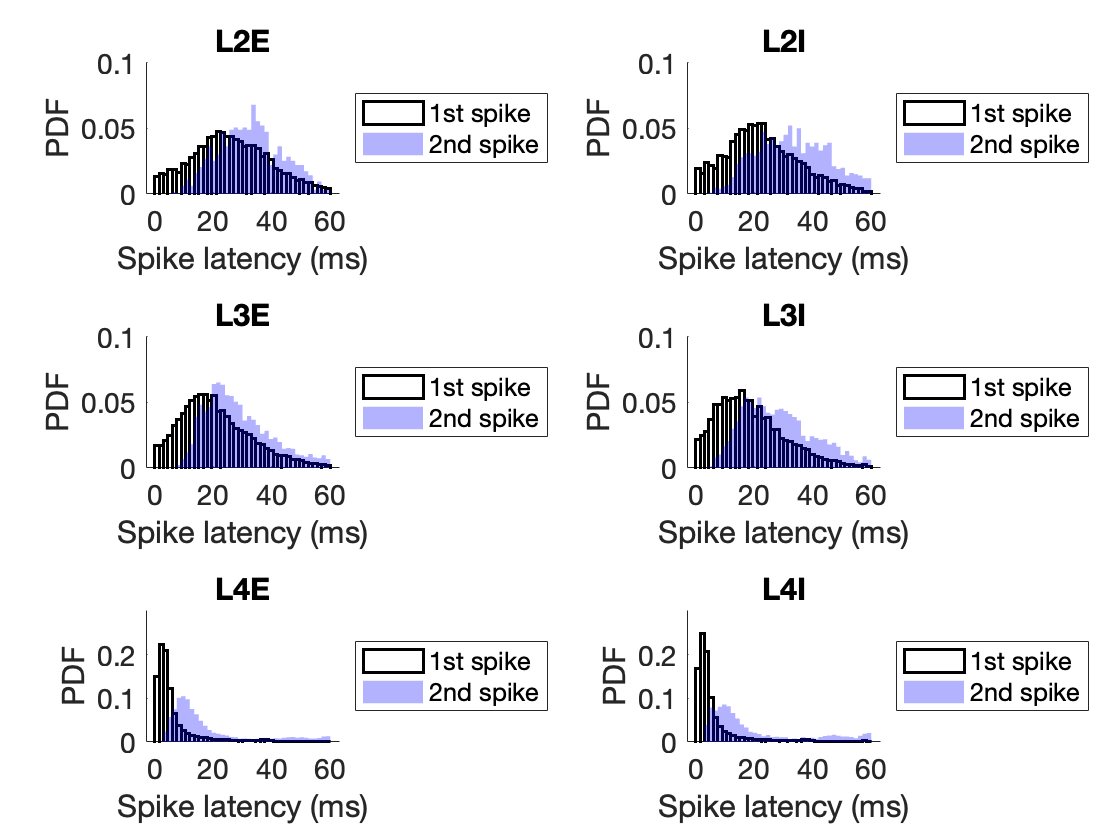

% analyse latency (method: time to first spike)
clearvars -except SNN_analysed pops SaveFigures *Path CortPopColorTags

f1 = figure; clf; tiledlayout(3,2);
f2 = figure; clf; tiledlayout(1,3);
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

k2=1;
maxLat = 60; % in ms
binSize = 1.5; % in ms

newAnalysis = 0;

if ~newAnalysis
    cd(AnalysisPath)
    load('SpikeLatency_Analysis_Baseline.mat')
else
    delete(gcp('nocreate'))
    parpool('local', 10);
    allSpikesData = [];
end

for jj=1:6
    if newAnalysis
        tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
        
        evs = cell2mat(cellfun(@(x) numel(x), tbl.VPMEventData,'uniformoutput',false));
        f_spk = {};
        s_spk = {};
        
        nnum = length(tbl.SpikeTimes{1,1});
        
        parfor ii = 1:length(evs)
            data_first = [];
            data_second = [];
            for kk = 1:evs(ii)
                for gg = 1:nnum
                    if ~isempty(tbl.VPMEventData{ii,1}{1, kk}.FirstSpikeLatency{1, gg})
                        data_first(end+1,1) = tbl.VPMEventData{ii,1}{1, kk}.FirstSpikeLatency{1, gg};
                    end
                    if ~isempty(tbl.VPMEventData{ii,1}{1, kk}.SecondSpikeLatency{1, gg})
                        data_second(end+1,1) = tbl.VPMEventData{ii,1}{1, kk}.SecondSpikeLatency{1, gg};
                    end
                end
            end
            f_spk{ii,1} = data_first;
            s_spk{ii,1} = data_second;
        end
        allSpikesData.(pops(jj,:)).f_spk = f_spk;
        allSpikesData.(pops(jj,:)).s_spk = s_spk;
    else
        f_spk = allSpikesData.(pops(jj,:)).f_spk;
        s_spk = allSpikesData.(pops(jj,:)).s_spk;
    end
    figure(f1)
    nexttile; hold on;
    %% FIRST SPIKE
    histogram(cell2mat(f_spk),0:binSize:maxLat,'EdgeColor','k','FaceColor','none', 'normalization', "probability",'LineWidth',1.4);
    
    %% SECOND SPIKE
    histogram(cell2mat(s_spk),0:binSize:maxLat,'FaceColor','b','FaceAlpha',0.3,'EdgeColor','none', 'normalization', "probability");
    
    legend('1st spike', '2nd spike','location','eastoutside')
    title(pops(jj,:))
    xlabel('Spike latency (ms)')
    ylabel('PDF')
    set(gca,'fontsize',14)
    if contains(pops(jj,:), '4')
        ylim([0 0.3])
    else
        ylim([0 0.1])
    end
    
    figure(f2)
    nexttile(1, [1 2]); hold on;
    
    position1 = 1 + (jj-1)*2;
    position2 = 1.5 + (jj-1)*2;
    position3 = 2 + (jj-1)*2;
    position4 = 2.5 + (jj-1)*2;
    
    scatter(randi([position2*100-20 position2*100+20],1,length(cell2mat(s_spk)))/100, cell2mat(s_spk), 'markerfacecolor', 'b', 'markeredgecolor', 'none', 'MarkerFaceAlpha',0.1)
    boxplot(cell2mat(s_spk), 'positions',position1, 'symbol', '')
    
    scatter(randi([position4*100-20 position4*100+20],1,length(cell2mat(f_spk)))/100, cell2mat(f_spk), 'markerfacecolor', 'k', 'markeredgecolor', 'none', 'MarkerFaceAlpha',0.1)
    boxplot(cell2mat(f_spk), 'positions',position3, 'symbol', '')
    
%     violin(cell2mat(f_spk),'x',k2,'facecolor','k','facealpha',0.3,'mc',[],'medc','k');
%     k2 = k2+1;
%     violin(cell2mat(s_spk),'x',k2,'facecolor','b','facealpha',0.2,'mc',[],'medc','b');
%     k2 = k2+1;
end

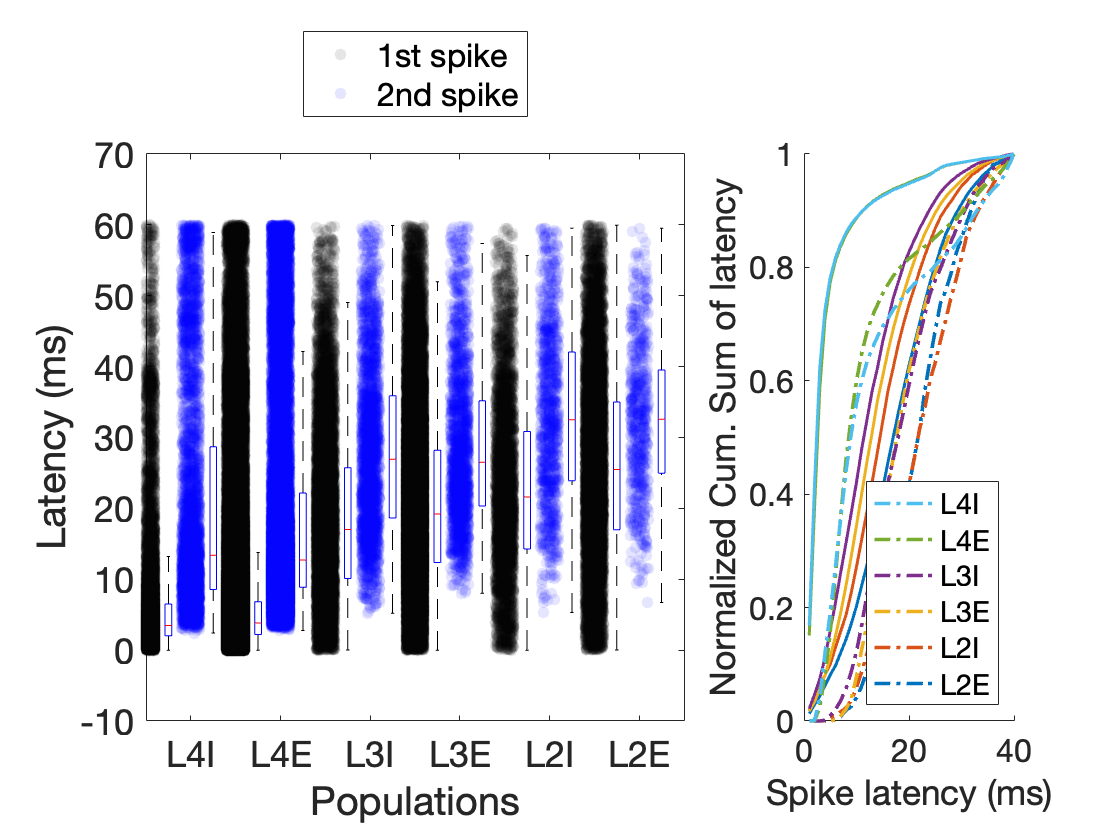

figure(f2); nexttile(1)
xlabel('Populations')
ylabel('Latency (ms)')
set(gca,'fontsize',18, 'xdir', 'reverse')
ax = gca; 
ax.XTickMode = 'manual';
ax.XTick = [1.5:2:13];
ax.XTickLabels=pops;
ax=get(gca,'Children');
legend(ax([2 4]),'1st spike', '2nd spike','location','northoutside')
ylim([-10 70])
xlim([-.5 14])


CortPopColorTags = [0.0000 0.4470 0.7410;... % blue,   l2E
    0.8500 0.3250 0.0980;... % orange,    l2I
    0.9290 0.6940 0.1250;... % yellow,    l3E
    0.4940 0.1840 0.5560;... % purple,    l3I
    0.4660 0.6740 0.1880;... % green,     l4E
    0.3010 0.7450 0.9330;... % light blue,l4I
    0.6350 0.0780 0.1840];

for ii = 1:6
    figure(f2);
    nexttile(3); hold on; % first spikes
    pop = pops(ii,:);
    
    latency_data = histcounts(cell2mat(allSpikesData.(pop).f_spk),0:binSize:maxLat);
    cumsum_data = cumsum(latency_data);
    sum_data = sum(latency_data);
    
    plot([cumsum_data/sum(latency_data)], 'linewidth', 1.5, 'color', CortPopColorTags(ii,:))
    
    nexttile(3); hold on; % second spikes
    latency_data = histcounts(cell2mat(allSpikesData.(pop).s_spk),0:binSize:maxLat);
    cumsum_data = cumsum(latency_data);
    sum_data = sum(latency_data);
    
    plot([cumsum_data/sum(latency_data)], 'linewidth', 1.8, 'color', CortPopColorTags(ii,:), "LineStyle",'-.')
end
xlabel('Spike latency (ms)')
ylabel('Normalized Cum. Sum of latency')
set(gca,'fontsize',16)

ax=get(gca,'Children');
legend(ax([1:2:end]),flipud(pops), 'location', 'southeast')


if newAnalysis
    cd(AnalysisPath)
    save('SpikeLatency_Analysis_Baseline', 'allSpikesData','-v7.3')
end

f3 = figure; clf; tiledlayout(2,4)


for jj=1:2:6
    e_first = cell2mat(allSpikesData.(pops(jj,:)).f_spk);
    i_first = cell2mat(allSpikesData.(pops(jj+1,:)).f_spk);
    
    e_second= allSpikesData.(pops(jj,:)).s_spk;
    i_second = allSpikesData.(pops(jj+1,:)).s_spk;
    
    nexttile(1,[2 2]); hold on;
    
    
    nexttile(3,[2 2]); hold on;
end

% if SaveFigures
%     cd(FiguresPath)
%     f=gcf;
%     set(f, 'paperorientation', 'landscape', 'renderer','painter')
%     print(f,'Baseline_latency', '-dpdf','-bestfit')
% end

% average correlations (single-neurons)
% i have to analyse top 5, 10, 15 and 20% of the active neurons
% plot cross correlation
clearvars -except SNN_analysed pops SaveFigures *Path CortPopColorTags

SaveIt = 1;
PlotIt = 1;
TopCorrelated = [5; 10; 15; 20];

XCLimits = [-60 0];
XCarray = [-60:6:0];% 6:6:60];
MostCorrelatedSingleNeurons = [];

if PlotIt
    cd(FiguresPath)
    f1 = figure; clf; tiledlayout(3,4);
    f2 = figure; clf; tiledlayout(3,4);
    f3 = figure; clf; tiledlayout(3,2);
end

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
for pop = 1:length(pops)
    ThisPop = pops(pop,:);
    MostCorrelatedSingleNeurons(end+1).Pop = ThisPop;
    
    SortedData.SingleNeuron = [];
    SortedData.Pop = [];
    SigToPlot_single = [];
    SigToPlot_pop = [];
    SortedRaw = [];
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, ThisPop),:);
    for ii = 1:size(tbl,1)
        SingleNeuronXCorr = tbl.SingleNeuronPSTH_XCorr{ii,1};
        PopXCorr = tbl.PopulationPSTH_XCorr{ii,1};
        
        NeuronNum = size(SingleNeuronXCorr,1);
        
        % trim raw signals
        LagsInMs = tbl.SingleNeuronPSTH_XCorrLags{ii,1}(1,:) * tbl.PSTHBinSize{ii,1};
        
        xLeft = find(ismember(LagsInMs,XCLimits(1)));
        xRight = find(ismember(LagsInMs,XCLimits(2)));
        LagsLimits = LagsInMs(:,xLeft:xRight);
        
        TrimmedSignals_single = SingleNeuronXCorr(:,xLeft:xRight);
        TrimmedSignals_pop = PopXCorr(:,xLeft:xRight);
        
        
        %%%%% normalize to single-neuron AUC
        NormToSingleNeuron = cell2mat(arrayfun(@(x) TrimmedSignals_single(x,:) / trapz(TrimmedSignals_single(x,:)), 1:NeuronNum, 'uniformoutput', false)');
        % sort for maximal value
        MaxXCorr = max(NormToSingleNeuron,[],2);
        [~, SortIndices] = sort(MaxXCorr, 'descend');
        SingleNeuronXCorrSorted = NormToSingleNeuron(SortIndices,:);
        % store sorted normalized data
%         SortedData.SingleNeuron{ii,1} = SingleNeuronXCorrSorted;
        
        
        %%%%% normalize to pop AUC
        NormToPop = cell2mat(arrayfun(@(x) TrimmedSignals_single(x,:) / trapz(TrimmedSignals_pop), 1:NeuronNum, 'uniformoutput', false)');
        % sort for maximal value
        MaxXCorr = max(NormToPop,[],2);
        [~, SortIndices] = sort(MaxXCorr, 'descend');
        PopXCorrSorted = NormToPop(SortIndices,:);
        % store sorted normalized data
%         SortedData.Pop{ii,1} = PopXCorrSorted;
        
        % select datapoints for plotting
        IdxToPlot = find(ismember(LagsLimits,XCarray));
        ZeroIdx = find(ismember(XCarray,0));
        
        SigToPlot_single(1:NeuronNum,1:length(IdxToPlot),ii) = SingleNeuronXCorrSorted(:,IdxToPlot);
        SigToPlot_pop(1:NeuronNum,1:length(IdxToPlot),ii) = PopXCorrSorted(:,IdxToPlot);
        
        % sorted raw
        MaxXCorr = max(TrimmedSignals_single,[],2);
        [~, SortIndices] = sort(MaxXCorr, 'descend');
        SortedRaw(1:NeuronNum,1:length(IdxToPlot),ii) = TrimmedSignals_single(SortIndices,IdxToPlot);
        
%         AUCNorm = SingleNeuronXCorrSorted;
        
%         % top most correlated
%         for top = 1:length(TopCorrelated)
%             MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.Raw = TrimmedSignals_single(1:round(NeuronNum*(TopCorrelated(1)/100)),:);
%             MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.Raw = TrimmedSignals_single(1:round(NeuronNum*(TopCorrelated(2)/100)),:);
%             MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.Raw = TrimmedSignals_single(1:round(NeuronNum*(TopCorrelated(3)/100)),:);
%             MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.Raw = TrimmedSignals_single(1:round(NeuronNum*(TopCorrelated(4)/100)),:);
%             
%             Sig5 = AUCNorm(1:round(NeuronNum*(TopCorrelated(1)/100)),:);
%             Sig10 = AUCNorm(1:round(NeuronNum*(TopCorrelated(2)/100)),:);
%             Sig15 = AUCNorm(1:round(NeuronNum*(TopCorrelated(3)/100)),:);
%             Sig20 = AUCNorm(1:round(NeuronNum*(TopCorrelated(4)/100)),:);
%             MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.AUCNorm = Sig5;
%             MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.AUCNorm = Sig10;
%             MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.AUCNorm = Sig15;
%             MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.AUCNorm = Sig20;
%             
%             % get the power and temporal profile of these signals
%             MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.Power = cell2mat(arrayfun(@(x) mean(abs(Sig5(x,:)).^2), 1:size(Sig5,1), 'UniformOutput',false)');
%             MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.Power = cell2mat(arrayfun(@(x) mean(abs(Sig10(x,:)).^2), 1:size(Sig10,1), 'UniformOutput',false)');
%             MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.Power = cell2mat(arrayfun(@(x) mean(abs(Sig15(x,:)).^2), 1:size(Sig15,1), 'UniformOutput',false)');
%             MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.Power = cell2mat(arrayfun(@(x) mean(abs(Sig20(x,:)).^2), 1:size(Sig20,1), 'UniformOutput',false)');
%             
%             MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.Latency = cell2mat(arrayfun(@(x) LagsLimits(find(Sig5(x,:)==max(Sig5(x,:)),1)),1:size(Sig5,1), 'UniformOutput',false));
%             if size(MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.Latency,2) ~= size(Sig5,1)
%                 Padding = diff([size(MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.Latency,2), size(Sig5,1)]);
%                 MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.Latency = [MostCorrelatedSingleNeurons(end).SparseData.Top5{ii,1}.Latency nan(1,abs(Padding))];
%             end
%             
%             MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.Latency = cell2mat(arrayfun(@(x) LagsLimits(find(Sig10(x,:)==max(Sig10(x,:)),1)),1:size(Sig10,1), 'UniformOutput',false));
%             if size(MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.Latency,2) ~= size(Sig10,1)
%                 Padding = diff([size(MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.Latency,2), size(Sig10,1)]);
%                 MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.Latency = [MostCorrelatedSingleNeurons(end).SparseData.Top10{ii,1}.Latency nan(1,abs(Padding))];
%             end
%             
%             MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.Latency = cell2mat(arrayfun(@(x) LagsLimits(find(Sig15(x,:)==max(Sig15(x,:)),1)),1:size(Sig15,1), 'UniformOutput',false));
%             if size(MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.Latency,2) ~= size(Sig15,1)
%                 Padding = diff([size(MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.Latency,2), size(Sig15,1)]);
%                 MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.Latency = [MostCorrelatedSingleNeurons(end).SparseData.Top15{ii,1}.Latency nan(1,abs(Padding))];
%             end
%             
%             MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.Latency = cell2mat(arrayfun(@(x) LagsLimits(find(Sig20(x,:)==max(Sig20(x,:)),1)),1:size(Sig20,1), 'UniformOutput',false));
%             if size(MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.Latency,2) ~= size(Sig20,1)
%                 Padding = diff([size(MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.Latency,2), size(Sig20,1)]);
%                 MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.Latency = [MostCorrelatedSingleNeurons(end).SparseData.Top20{ii,1}.Latency nan(1,abs(Padding))];
%             end
%         end
    end
    
    if PlotIt
        %%% single-neuron normalization
        figure(f1)
        nexttile; hold on;
        
        SigToPlot_single(isnan(SigToPlot_single)) = 0;
        PlotAll = nanmean(SigToPlot_single,3);
        
        imagesc(PlotAll)
        
        title(ThisPop)
        ax = gca;
        ax.XTickMode = 'manual';
        ax.XTick = 1:length(XCarray);%find(ismember(LagsInMs,XCarray));
        ax.XTickLabel = XCarray;
%         xlim([find(ismember(LagsInMs,XCLimits(1))) find(ismember(LagsInMs,XCLimits(2)))])
        xlim([1 length(XCarray)])
        ylim([0 NeuronNum])
        xlabel('Lag (ms)')
        ylabel('Neuron')
        cb = colorbar;
        ylabel(cb,'<CC (norm. to neuron)>')
        caxis([0 0.1])
        set(gca,'fontsize', 14, 'ydir', 'reverse')
        
        nexttile;
        SumYAxis = PlotAll(:,1:ZeroIdx);
        stdShade(SumYAxis', 0.2, 'k', 1:NeuronNum)
        xlim([0 NeuronNum])
        ylabel('Mean CC')
        set(gca,'fontsize', 14, 'ydir', 'reverse')
        view([270 -90])
        
        
        %%% pop normalization
        figure(f2)
        nexttile; hold on;
        
        SigToPlot_pop(isnan(SigToPlot_pop)) = 0;
        PlotAll = nanmean(SigToPlot_pop,3);
        
        imagesc(PlotAll)
        
        title(ThisPop)
        ax = gca;
        ax.XTickMode = 'manual';
        ax.XTick = 1:length(XCarray);%find(ismember(LagsInMs,XCarray));
        ax.XTickLabel = XCarray;
%         xlim([find(ismember(LagsInMs,XCLimits(1))) find(ismember(LagsInMs,XCLimits(2)))])
        xlim([1 length(XCarray)])
        ylim([0 NeuronNum])
        xlabel('Lag (ms)')
        ylabel('Neuron')
        cb = colorbar;
        ylabel(cb,'<CC (norm. to pop)>')
        if contains(ThisPop, 'I')
            caxis([0 0.008])
        else
            caxis([0 0.002])
        end
        set(gca,'fontsize', 14)
        
        nexttile;
        SumYAxis = PlotAll(:,1:ZeroIdx);
        stdShade(SumYAxis', 0.2, 'k', 1:NeuronNum)
        xlim([0 NeuronNum])
        ylabel('Mean CC')
        set(gca,'fontsize', 14)
        view([90 -90])
        
        figure(f3) %sorted raw data
        nexttile;
        imagesc(sum(SortedRaw,3))
        title(ThisPop)
        ax = gca;
        ax.XTickMode = 'manual';
        ax.XTick = 1:length(XCarray);
        ax.XTickLabel = XCarray;
        xlim([1 length(XCarray)])
        ylim([0 NeuronNum])
        xlabel('Lag (ms)')
        ylabel('Neuron')
        cb = colorbar;
        ylabel(cb,'sum(CC)')
        if contains(ThisPop, '2')
            caxis([0 6e3])
        elseif contains(ThisPop, '3')
            caxis([0 12e3])
        elseif contains(ThisPop, '4')
            caxis([0 6e4])
        end
        set(gca,'fontsize', 14, 'ydir', 'reverse')
    end
end

if SaveFigures
    cd(FiguresPath)
    figure(f1)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'XCorr_single_normToSingle', '-dpdf','-bestfit')
    
    figure(f2)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'XCorr_single_normToPop', '-dpdf','-bestfit')
    
    figure(f3)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'XCorr_single_rawSorted', '-dpdf','-bestfit')
end

% normalized correlations (population-wide)
clearvars -except SNN_analysed pops SaveFigures *Path CortPopColorTags

CortPopColorTags = [0.0000 0.4470 0.7410;... % blue,   l2E
0.8500 0.3250 0.0980;... % orange,    l2I
0.9290 0.6940 0.1250;... % yellow,    l3E
0.4940 0.1840 0.5560;... % purple,    l3I
0.4660 0.6740 0.1880;... % green,     l4E
0.3010 0.7450 0.9330;... % light blue,l4I
0.6350 0.0780 0.1840];

SignalPower = [];
TempDelay = [];
NormalizedToAUC = [];

XCLimits = [-60 0];

figure; clf; tiledlayout(1,4); nexttile([1 2]); hold on;

for jj=1:6    
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    PopNeuronXCorr = tbl.PopulationPSTH_XCorr;
    LagsInMs = tbl.PopulationPSTH_XCorrLags{1,1} * tbl.PSTHBinSize{1,1};
    
    xLeft = find(ismember(LagsInMs,XCLimits(1)));
    xRight = find(ismember(LagsInMs,XCLimits(2)));
    LagsLimits = LagsInMs(:,xLeft:xRight);
    
    TrimmedSignals_single = cellfun(@(x) x(:,xLeft:xRight), PopNeuronXCorr, 'UniformOutput',false);
    AUCNorm = cellfun(@(x) x/trapz(x), TrimmedSignals_single, 'UniformOutput',false);
    
%         FirstNormThenMean = mean(cell2mat(cellfun(@(x) x/trapz(x), TrimmedSignals, 'UniformOutput',false)));
%         FirstMeanThenNorm = mean(cell2mat(TrimmedSignals)) / trapz(mean(cell2mat(TrimmedSignals)));
    
    NormalizedToAUC{jj,1} = mean(cell2mat(AUCNorm),1);
    
    halfAUCNorm = find(LagsLimits == 0);
    SignalPower{jj,1} = cellfun(@(x) mean(abs(x(:,1:halfAUCNorm)).^2), AUCNorm, 'UniformOutput',false);
    TempDelay{jj,1} = cellfun(@(x) LagsLimits(find(x==max(x),1)),AUCNorm, 'UniformOutput',false);
    
    plot(LagsLimits,NormalizedToAUC{jj,1},'linewidth',1.4, 'color', CortPopColorTags(jj,:))
%     stdShade(cell2mat(AUCNorm),0.18,CortPopColorTags(jj,:),LagsLimits)
end
xlabel('Lag (ms)')
ylabel('XCorr / AUC(XCorr)')
ylim([0 0.2])
legend(pops, 'location', 'northwest')
set(gca,'fontsize',18)

for ii = 1:6
    nexttile(3); hold on;
    data = cell2mat(cellfun(@(x) cell2mat(x), SignalPower(ii,:), 'uniformoutput',false));
    boxplot(data,'positions',ii,'colors',CortPopColorTags(ii,:),'symbol','o','plotstyle','compact', 'medianstyle','line', 'Widths',2, 'whisker', 1.5);

    nexttile(4); hold on;
    data = cell2mat(cellfun(@(x) cell2mat(x), TempDelay(ii,:), 'uniformoutput',false));
    data(data>0) = NaN;
    boxplot(data,'positions',ii,'colors',CortPopColorTags(ii,:),'symbol','o','plotstyle','compact', 'medianstyle','line', 'Widths',2, 'whisker', 1.5);
end

nexttile(3);
ax = gca;
ax.XTickMode = 'manual';
ax.XTick = 1:6;
ax.XTickLabel = pops;
xlabel('Populations')
ylabel('Power (< XCorr \^ 2 >)')
ylim([2 9]*1e-3)
title('Power analysis')
set(gca,'fontsize', 14, 'xdir', 'reverse')

nexttile(4);
ax = gca;
ax.XTickMode = 'manual';
ax.XTick = 1:6;
ax.XTickLabel = pops;
xlabel('Populations')
ylabel('Peak XCorr (ms)')
ylim([-65 5])
title('Temporal profile analysis')
set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,'XCorr_pop', '-dpdf','-bestfit')
end

return
% response detectability
% compare (RTAs v ETAs) and (nETAs v ETAs) distributions with KL divergence
clearvars -except SNN_analysed SaveFigures

% ETA: FRs sampled from within-event window
% nETA: FRs sampled from out-of-event window
% RTA: FRs sampled randomly from full simulation time
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I';'VPM'];

time_bin = 5; % ms
total_time = max(unique(cell2mat(SNN_analysed.SimulationDuration)));
discarded_time = 100; % ms

fr_bin = 5; % Hz

comparison = 'nETAs'; % nETAs or RTAs

figure; clf; tiledlayout(3,2)
for jj=1:6
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    
    if contains(pops(jj,:),'2I')
        FR_distribution = 0:2:250;
    elseif contains(pops(jj,:),'2E')
        FR_distribution = 0:0.5:50;
    elseif contains(pops(jj,:),'3I')
        FR_distribution = 0:2:150;
    elseif contains(pops(jj,:),'3E')
        FR_distribution = 0:0.5:50;
    elseif contains(pops(jj,:),'4')
        FR_distribution = 0:3:300;
    end
    
    % get all spike times per simulation
    ETA_spikes = cellfun(@(x) cell2mat(x'),tbl.ETA_spikes, 'uniformoutput', false);
    
    % get the number of participating neurons
    ETA_participation = [];
    for simNum = 1:size(tbl,1)
        ETA_participation{simNum,1} = sum(cell2mat(cellfun(@(x) isempty(x),tbl.ETA_spikes{simNum,1}, 'uniformoutput', false)));
    end
    
    % make PSTH from spike times
    true_PSTH = cellfun(@(x, y) histcounts(x, 0:time_bin:y+discarded_time), ETA_spikes, tbl.SimulationDuration, 'uniformoutput', false);
   
    switch comparison
        case 'nETAs'
            nETA_spikes = cellfun(@(x) cell2mat(x'),tbl.nETA_spikes, 'uniformoutput', false);
            approx_participation = [];
            for simNum = 1:size(tbl,1)
                approx_participation{simNum,1} = sum(cell2mat(cellfun(@(x) isempty(x),tbl.nETA_spikes{simNum,1}, 'uniformoutput', false)));
            end
            approx_PSTH = cellfun(@(x, y) histcounts(x, 0:time_bin:y+discarded_time), nETA_spikes, tbl.SimulationDuration, 'uniformoutput', false);
        case 'RTAs'
            approx_PSTH = cellfun(@(x, y) histcounts(x, 0:time_bin:y+discarded_time), tbl.RTA_spikes, tbl.SimulationDuration, 'uniformoutput', false);
            approx_participation = ETA_participation;
    end
    
    % calculate FR from PSTH
    true_FR = cellfun(@(x, y) (x./(time_bin/1000))/y, true_PSTH, ETA_participation, 'uniformoutput', false);
    approx_FR = cellfun(@(x, y) (x./(time_bin/1000))/y, approx_PSTH, approx_participation, 'uniformoutput', false);

    % make FR distrubutions
    p=histcounts(cell2mat(true_FR'),FR_distribution,'Normalization','probability'); %true distribution
    q=histcounts(cell2mat(approx_FR'),FR_distribution,'Normalization','probability'); %approximative distribution
    kl = KL_Div_hist(p,q,FR_distribution);
    
    nexttile; hold on;

    histogram(cell2mat(true_FR'),FR_distribution,'Normalization','probability','EdgeColor','none','FaceColor','b','FaceAlpha',0.4); %true distribution
    histogram(cell2mat(approx_FR'),FR_distribution,'Normalization','probability','EdgeColor','none','FaceColor','k','FaceAlpha',0.4); %approximative distribution
    title(sprintf('%s KL=%0.5f',pops(jj,:), kl))
    
    legend('ETAs', comparison)
%     xlim([-5 100])
    ylim([0 0.01])
    xlabel('spikes/s')
    ylabel('neurons (%)')
    set(gca,'fontsize',14)
end

% alternative way to sample from FR distributions in- and out- of VPM
% events
...